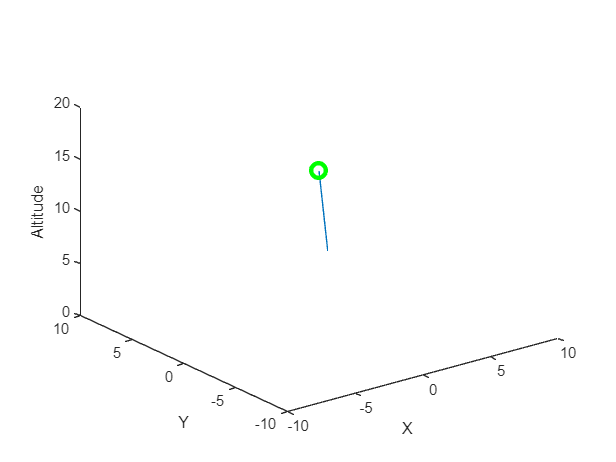

Unrecognized function or variable 'Xshow'.

clc
clear

%load("nonlinearModelData.mat")
load("Ploting/LinearData.mat")

l = 8; %if changed in model change here also

% Xp = Xshow(1,:) + l .* sin(Xshow(4,:)) .*cos(Xshow(5,:));
% Yp = Xshow(2,:) + l .* sin(Xshow(4,:)) .*sin(Xshow(5,:));
% Zp = Xshow(3,:) - l.* cos(Xshow(4,:));


Xup = 10;
Xlow =-10;
Yup = 10;
Ylow =-10;
Zup = 20;
Zlow =0;

figh = figure;
for i =1 : length(Xshow)

    clf

    Xa_i = Xshow(1,i);
    Ya_i = Xshow(2,i);
    Za_i = Xshow(3,i);
    
    Xp_i = Xp(i);
    Yp_i = Yp(i);
    Zp_i = Zp(i);
    

    connect = [Xa_i Ya_i Za_i;Xp_i Yp_i Zp_i];
     
    plot3(Xa_i,Ya_i,Za_i, 'go','LineWidth',3,'MarkerSize',10)
     xlim([Xlow Xup]);
     ylim([Ylow Yup]);
     zlim([Zlow Zup]);
     xlabel('X')
    ylabel('Y')
    zlabel('Altitude')
     
    hold on
    line(connect(:,1),connect(:,2),connect(:,3))
    plot3(Xshow(1,:),Xshow(2,:),Xshow(3,:),'g:')
    plot3(Xp,Yp,Zp,'b:')
    plot3(Xp_i,Yp_i,Zp_i, 'bo','LineWidth',3,'MarkerSize',5)
    view([-2.6 17.6])
    if Xa_i < min(get(gca, 'XLim'))
        Xlow = Xa_i-30;
    elseif Xa_i > max(get(gca, 'XLim'))
        Xup = Xa_i+30;
    end
    if Ya_i < min(get(gca, 'YLim'))
        Ylow = Ya_i-30;
    elseif Ya_i > max(get(gca, 'YLim'))
        Yup = Ya_i+30;
    end
    
    if Zp_i < min(get(gca, 'ZLim'))
        Zlow = Zp_i-30;
    elseif Zp_i > max(get(gca, 'ZLim'))
        Zup = Zp_i+30;
    end
    
    movieVector(i) = getframe(figh,[10 10 520 400] );
 
end

   myWriter = VideoWriter('LinearSim_Alpha10Beta10_MovingMovie','MPEG-4');
   myWriter.FrameRate = 10;

   open(myWriter);
   writeVideo(myWriter,movieVector);
   close(myWriter);